# Primary Strut Buckling Analysis

We model the telescopic arm as follows:

The first 3 segments are considered as flexible Eulero-Bernoulli beams, capable of carrying all type of stresses but with infinite shear rigidity. This allows us to decouple the flexibility and compressibility prolems, and study them separately. Each segment has its length $L_i$ and bending inertia moment $I_i$.

The last 2 segments are the outer and inner hydro-pneumatic damper, and, being pressurized, are resistent to buckling (at least considerably more than the longer and more slender first 3 segments), and are thus considered fused as a rigid beam, of length $L_4 \;+L_5 \;$.

By hypothesis we work in a framework of small displacements. i.e.:


$$\tan(\theta)\approx \sin(\theta) \approx \theta,\ \cos(\theta) \approx 1$$


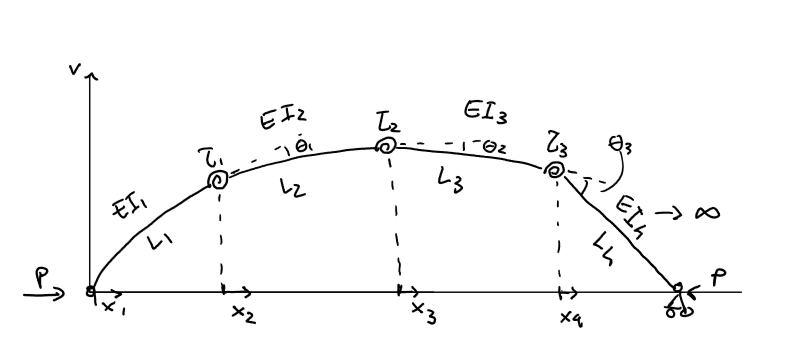

## Flexible Segments

The Eulero Bernoulli beam flexibility equation is:


$$v''_i(x_i)+\frac{P}{EI_i}v_i(x_i)=0
$$


Resulting in a general displacement equation valid for any flexible segment:


$$\begin{cases}
v_i(x_i)=A_i\cos(k_ix_i)+B_i\sin(k_ix_i)\\
v_i'(x_i)=-k_iA_i\sin(k_ix_i) + k_iB_i\cos(k_ix_i)
\end{cases}
$$


With $k_i=\sqrt\frac{P}{EI_i}$

## Rigid Segment

The Rigid segment has displacement equation:


$$v_n(x_n)=A_nx_n+B_n$$


Generalized for the case of n+1 segments for the telescopic arm.

## Bounduary Conditions

At the end caps, the displacement is null:


$$\begin{cases}
v_1(0)=0\\
v_n(L_n)=0
\end{cases}$$
 

## Compatibility Equations

Clearly, the displecement at the connections must be the same, and the change in inclination is directly proportionated to the local displacement and the torsional spring coefficient.

The first condition translates as;


$$\begin{cases}
v_1(L_1)=v_2(0)\\
v_2(L_2)=v_3(0)\\
\vdots\\
v_{n-1}(L_{n-1})=v_n(0)
\end{cases}$$
 

Since, at any point along the strut: $M(x)=-Pv(x)$, the springs flex by $\theta_i = \frac{M(L_i)}{\tau_i}=-\frac{Pv_i(L_i)}{\tau_i}=-k_i^2\gamma_iv_i(L_i)
$

where $\gamma_i = \frac{EI_i}{\tau_i}$

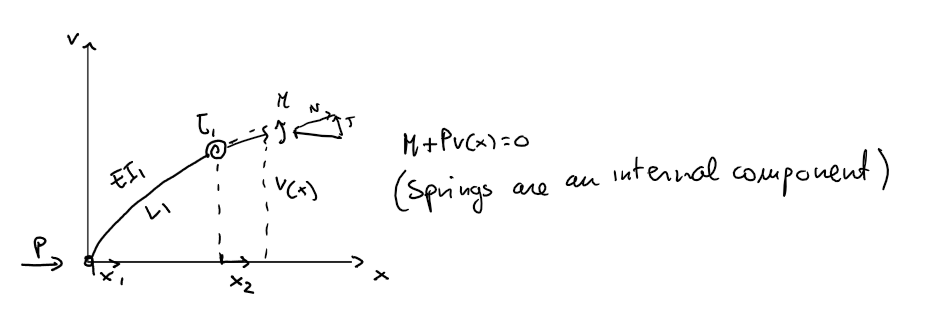

Therefore:


$$v_i'(L_i)-k_i^2\gamma_iv_i(L_i)=v_{i+1}'(0)$$


We now want to solve the system of homogeneus equations relative to BC and CE to find values of P that allow for a shape (different from the straight one) that will consist of the buckled equilibrium configuration. 

We analyze the 3 springs case (3 flexible segment + 1 rigid, made by the last two).

% symbolic variables initialization
clear

Li = sym('L_i','positive');
L1 = sym('L_1','positive');
L2 = sym('L_2','positive');
L3 = sym('L_3','positive');
L4 = sym('L_4','positive');

ki = sym('k_i','positive');
k1 = sym('k_1','positive');
k2 = sym('k_2','positive');
k3 = sym('k_3','positive');
k4 = sym('k_4','positive');

t1 = sym('tau_1','positive');
t2 = sym('tau_2','positive');
t3 = sym('tau_3','positive');

g = sym('gamma','positive');
gi = sym('gamma_i','positive');
g1 = sym('gamma_1','positive');
g2 = sym('gamma_2','positive');
g3 = sym('gamma_3','positive');

% At first we write the BC mixed with the displacement CE

BCMatrix=[1, 0, 0, 0, 0, 0, 0, 0
    cos(k1*L1), sin(k1*L1), -1, 0, 0, 0, 0, 0
    0, 0, cos(k2*L2), sin(k2*L2), -1, 0, 0, 0
    0, 0, 0, 0, cos(k3*L3), sin(k3*L3), 0, -1
    0, 0, 0, 0, 0, 0, L4, 1]


% we write the inclination CE

% afret soving discontinuity equations in terms of v_i e v_i', i substitute
% the general expression and group the same coefficients, which multiply
% the following functions:

fAi=-ki*sin(ki*Li)-ki^2*gi*cos(ki*Li);
fBi=ki*cos(ki*Li)-ki^2*gi*sin(ki*Li);

fA11=subs(fAi,[ki Li gi],[k1 L1 g1]);
fB11=subs(fBi,[ki Li gi],[k1 L1 g1]);
fA21=k2*sin(k2*L2);
fB21=-k2*cos(k2*L2);

fA22=subs(fAi,[ki Li gi],[k2 L2 g2]);
fB22=subs(fBi,[ki Li gi],[k2 L2 g2]);
fA32=k3*sin(k3*L3);
fB32=-k3*cos(k3*L3);

fA33=subs(fAi,[ki Li gi],[k3 L3 g3]);
fB33=subs(fBi,[ki Li gi],[k3 L3 g3]);

CEMatrix=[fA11 fB11 fA21 fB21 0 0 0 0
    0 0 fA22 fB22 fA32 fB32 0 0
    0 0 0 0 fA33 fB33 -1 0]

% so, we have the matrix we want to find the determinant of:

M=[BCMatrix;CEMatrix];

% e mo famo ildeterminante

detM= det(M);
detM=simplify(detM)



## Critical Load

To find the value of the critical load we must solve for the determinat equal to zero. 

From the ralation, we take values that should help us simplifying the determinant.

The idea is

- 
$$I_i=I\rho^{(i-1)}
$$


- 
$$\begin{cases}
L_i=L_1-(i-1)\Delta L \ for\ i<n\\
L_n=2L_1-(2n-1)\Delta L \ for \ i=n
\end{cases}
$$
 

Consequently, since $k_i=\sqrt{P/EI_i}$

- 
$$k_1=\sqrt{P/EI_1}$$


- 
$$k_i=k_1\rho^{(1-i)/2}$$


Then, we can set $\gamma_i=\gamma$, signifying that the relation between flexural rigidity and spring constant is the same for every segment#

i.e.:

- 
$$\rho = 0.9$$


- 
$$\Delta L = L/10$$


detM=subs(detM,[g1 g2 g3],[g g g])

rho=0.9
DL = L1/10

L2n = L1-DL
L3n = L1-2*DL
L4n = 2*L1 -7*DL

k2n = k1*rho^(-1/2)
k3n = k1*rho^(-1)

L1=2.5 %[m]

% detM=subs(detM,[L2 L3 L4 k2 k3],[L2n L3n L4n k2n k3n])
% detM=subs(detM,L2,L1-DL)
detM=subs(detM,L2,L2n)
detM=subs(detM,L3,L3n)
detM=subs(detM,L4,L4n)
detM=subs(detM,k2,k2n)
detM=subs(detM,k3,k3n)


simplify(detM)